# Convert MIDI Files into MIDI Messages

## Read MIDI File

%MIDI_file_name = 'etude_10_3.mid';
%MIDI_file_name = 'CmajorScale.mid';    
MIDI_file_name = 'Example_tox_shorts.mid';

readme = fopen(MIDI_file_name);
[readOut, byteCount] = fread(readme);
fclose(readme);
ticksPerQNote = polyval(readOut(13:14),256);

### Parse MIDI Track Chunk

% Initialize values
chunkIndex = 14;     % Header chunk is always 14 bytes
ts = 0;              % Timestamp - Starts at zero
BPM =97;
time_signature = 4; % ex) 4/4 or 3/4 ...
msgArray = [];


% Parse track chunks in outer loop
while chunkIndex < byteCount
    
    % Read header of track chunk, find chunk length   
    % Add 8 to chunk length to account for track chunk header length
    chunkLength = polyval(readOut(chunkIndex+(5:8)),256)+8;
    
    ptr = 8+chunkIndex;             % Determine start for MIDI event parsing
    statusByte = -1;                % Initialize statusByte. Used for running status support
    
    % Parse MIDI track events in inner loop
    while ptr < chunkIndex+chunkLength
        % Read delta-time
        [deltaTime,deltaLen] = findVariableLength(ptr,readOut);  
        % Push pointer to beginning of MIDI message
        ptr = ptr+deltaLen;
        
        % Read MIDI message
        [statusByte,messageLen,message] = interpretMessage(statusByte,ptr,readOut);
        % Extract relevant data - Create midimsg object
        [ts,msg] = createMessage(message,ts,deltaTime,ticksPerQNote,BPM);
        
        % Add midimsg to msgArray
        msgArray = [msgArray;msg];
        % Push pointer to next MIDI message
        ptr = ptr+messageLen;
    end
    
    % Push chunkIndex to next track chunk
    chunkIndex = chunkIndex+chunkLength;
end
disp(msgArray)

  MIDI message:
    NoteOn          Channel: 1  Note: 38  Velocity: 50  Timestamp: 0  [ 90 26 32 ]
    NoteOn          Channel: 1  Note: 50  Velocity: 59  Timestamp: 0.463918  [ 90 32 3B ]
    NoteOn          Channel: 1  Note: 53  Velocity: 64  Timestamp: 0.463918  [ 90 35 40 ]
    NoteOn          Channel: 1  Note: 57  Velocity: 64  Timestamp: 0.463918  [ 90 39 40 ]
    NoteOn          Channel: 1  Note: 64  Velocity: 64  Timestamp: 0.463918  [ 90 40 40 ]
    NoteOff         Channel: 1  Note: 38  Velocity: 0   Timestamp: 0.618557  [ 80 26 00 ]
    NoteOff         Channel: 1  Note: 50  Velocity: 0   Timestamp: 0.618557  [ 80 32 00 ]
    NoteOff         Channel: 1  Note: 53  Velocity: 0   Timestamp: 0.618557  [ 80 35 00 ]
    NoteOff         Channel: 1  Note: 57  Velocity: 0   Timestamp: 0.618557  [ 80 39 00 ]
    NoteOff         Channel: 1  Note: 64  Velocity: 0   Timestamp: 0.618557  [ 80 40 00 ]
    NoteOn          Channel: 1  Note: 40  Velocity: 54  Timestamp: 0.927835  [ 90 28 36 ]
 

## Split MIDI

( Example : etude_10_3 )

%if MIDI_file_name == 'etude_10_3.mid'
%    msgArray = msgArray(find([msgArray.Timestamp] > 250))
%end

## Note on Midi Array

on_msgArray = msgArray(find(int8([msgArray.Type]) == 1))

on_msgArray =   MIDI message:
    NoteOn          Channel: 1  Note: 38  Velocity: 50  Timestamp: 0  [ 90 26 32 ]
    NoteOn          Channel: 1  Note: 50  Velocity: 59  Timestamp: 0.463918  [ 90 32 3B ]
    NoteOn          Channel: 1  Note: 53  Velocity: 64  Timestamp: 0.463918  [ 90 35 40 ]
    NoteOn          Channel: 1  Note: 57  Velocity: 64  Timestamp: 0.463918  [ 90 39 40 ]
    NoteOn          Channel: 1  Note: 64  Velocity: 64  Timestamp: 0.463918  [ 90 40 40 ]
    NoteOn          Channel: 1  Note: 40  Velocity: 54  Timestamp: 0.927835  [ 90 28 36 ]
    NoteOn          Channel: 1  Note: 52  Velocity: 56  Timestamp: 1.39175  [ 90 34 38 ]
    NoteOn          Channel: 1  Note: 56  Velocity: 45  Timestamp: 1.39175  [ 90 38 2D ]
    NoteOn          Channel: 1  Note: 59  Velocity: 61  Timestamp: 1.39175  [ 90 3B 3D ]
    NoteOn          Channel: 1  Note: 62  Velocity: 59  Timestamp: 1.39175  [ 90 3E 3B ]
    NoteOn          Channel: 1  Note: 45  Velocity: 61  Timestamp: 2.47423  [ 90 

off_msgArray = msgArray(find(int8([msgArray.Type]) == 2))

off_msgArray =   MIDI message:
    NoteOff         Channel: 1  Note: 38  Velocity: 0   Timestamp: 0.618557  [ 80 26 00 ]
    NoteOff         Channel: 1  Note: 50  Velocity: 0   Timestamp: 0.618557  [ 80 32 00 ]
    NoteOff         Channel: 1  Note: 53  Velocity: 0   Timestamp: 0.618557  [ 80 35 00 ]
    NoteOff         Channel: 1  Note: 57  Velocity: 0   Timestamp: 0.618557  [ 80 39 00 ]
    NoteOff         Channel: 1  Note: 64  Velocity: 0   Timestamp: 0.618557  [ 80 40 00 ]
    NoteOff         Channel: 1  Note: 40  Velocity: 0   Timestamp: 1.54639  [ 80 28 00 ]
    NoteOff         Channel: 1  Note: 52  Velocity: 0   Timestamp: 1.54639  [ 80 34 00 ]
    NoteOff         Channel: 1  Note: 56  Velocity: 0   Timestamp: 1.54639  [ 80 38 00 ]
    NoteOff         Channel: 1  Note: 59  Velocity: 0   Timestamp: 1.54639  [ 80 3B 00 ]
    NoteOff         Channel: 1  Note: 62  Velocity: 0   Timestamp: 1.54639  [ 80 3E 00 ]
    NoteOff         Channel: 1  Note: 45  Velocity: 0   Timestamp: 2.93814

note_on = [ on_msgArray.Note ; on_msgArray.Velocity ; on_msgArray.Timestamp].'; % Note & Velocity to be int
note_off = [ off_msgArray.Note ; off_msgArray.Velocity ; off_msgArray.Timestamp].'; % Note & Velocity to be int

% All the notes within that second.
note_on

note_on =    38.0000   50.0000         0
   50.0000   59.0000    0.4639
   53.0000   64.0000    0.4639
   57.0000   64.0000    0.4639
   64.0000   64.0000    0.4639
   40.0000   54.0000    0.9278
   52.0000   56.0000    1.3918
   56.0000   45.0000    1.3918
   59.0000   61.0000    1.3918
   62.0000   59.0000    1.3918


max(note_off(:, 3))

ans = 4.9485

0:10

ans =      0     1     2     3     4     5     6     7     8     9    10


## Draw spiral

% height
if isempty(note_off)
    H = max(note_on(:, 3))+3 % +3s interval
else 
    % not exit "off MIDI"
    H = max(note_off(:, 3))
end

H = 4.9485


N = 12*4;   % 12 * 8 octaves ( ~ 9 octave) : 8 -> 4
r = 2^(1/12);

f_i = 55 % initial freq 

f_i = 55

note_i = 30 % initial note

note_i = 30

f = f_i*r.^(-32+note_i:N-2) % Octave 1 A = 55 Hz = 33 Note / if note_i = 30, f(1) = oct1 G

f =    48.9994   51.9131   55.0000   58.2705   61.7354   65.4064   69.2957   73.4162   77.7817   82.4069   87.3071   92.4986   97.9989  103.8262  110.0000  116.5409  123.4708  130.8128  138.5913  146.8324  155.5635  164.8138  174.6141  184.9972  195.9977  207.6523  220.0000  233.0819  246.9417  261.6256  277.1826  293.6648  311.1270  329.6276  349.2282  369.9944  391.9954  415.3047  440.0000  466.1638  493.8833  523.2511  554.3653  587.3295  622.2540  659.2551  698.4565  739.9888  783.9909


This yielded the same results as the MIDI chart.

theta = pi/2 - 2*pi*log2(f/f_i); % Clock Convention
% Z = zeros(1,length(f)); %same size
A = 1./f;

figure

% drawing key & spiral >> convert into surf?    
wk = pi/2 - pi/6*[0 2 3 5 7 8 10]; % white keys : A B C D E F G 
bk = pi/2 - pi/6*[1 4 6 9 11]; % black keys : A# C# D# F# G# 

R = A(1)

R = 0.0204

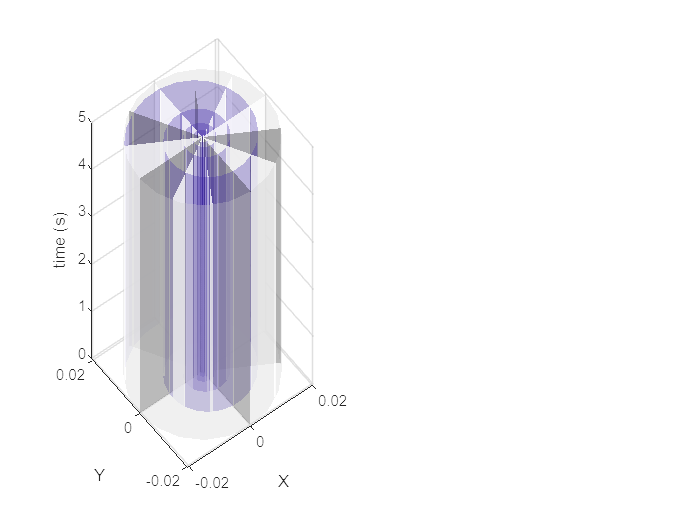

% drawing two graph
tiledlayout(1,2)
ax_3D = nexttile(1);

% drawing cyinders
[x y z_c] = cylinder(R);
ax_3D_cyl = surf(x, y, z_c*(H),'FaceColor',[.8 .8 .8],'EdgeAlpha',0, 'FaceAlpha',.3);
hold on;

% drawing spiral surf
P = 2; % parted

f_P = f_i*r.^(-32+note_i:1/P:N-2);
theta_P = pi/2 - 2*pi*log2(f_P/f_i);
A_P = 1./f_P;

[x y] = pol2cart(theta_P, A_P);
z_s = zeros(1, length(x));
ax_3D_spir = surf([x; x], [y; y], [z_s; z_s+H],'EdgeAlpha',0, 'FaceAlpha',.3);

% drawing white key
[xw yw] = pol2cart(wk, R);
[xb yb] = pol2cart(bk, R);

zero = zeros(1, length(xw));
x = reshape([zero; xw],1,[]);
y = reshape([zero; yw],1,[]);
z_w = zeros(1, length(xw)*2);
ax_3D_wk = surf([x; x], [y; y], [z_w;z_w+H],'FaceColor','w', 'FaceAlpha',.8, 'EdgeAlpha',0);

% drawing black key
zero = zeros(1, length(xb));
x = reshape([zero; xb],1,[]);
y = reshape([zero; yb],1,[]);
z_b = zeros(1, length(xb)*2);

ax_3D_bk = surf([x; x], [y; y], [z_b;z_b+H],'FaceColor','black', 'FaceAlpha',.3, 'EdgeAlpha',0);

xlabel('X')
ylabel('Y')
zlabel('time (s)')

max_note = length(theta)

max_note = 49

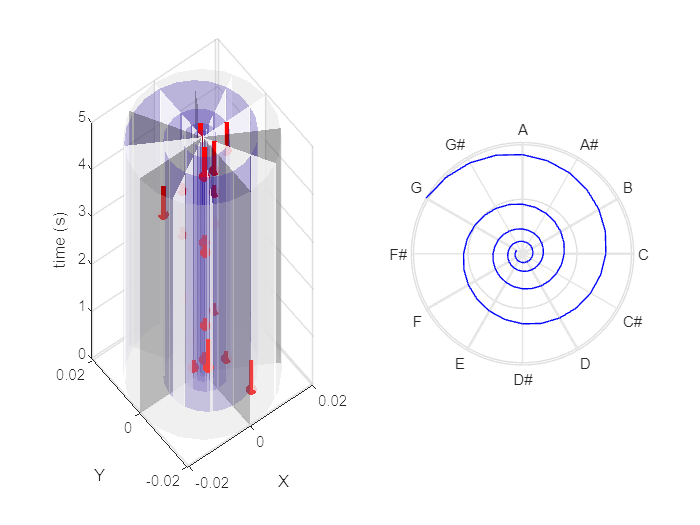


% Piano Note
for i=1:length(note_on)

    if isempty(note_off) && i~=length(note_on)
        note = [note_on(i,:).' ; note_on(i+1,:).'];
    elseif isempty(note_off)
        note = [note_on(i,:).' ; H];
    else
        note = [note_on(i,:).' ; note_off(i,3)]; % add end time ( ** modify - Working on it above )
    end

    n = note(1); v = note(2); st = note(3); et = note(4); 
    idx = n - note_i; % MIDI note number = Matlab index
    
    if (idx < max_note)
        [x y] = pol2cart(theta(idx), A(idx));
        plot3(x,y,st,'ro', 'MarkerFaceColor', 'r');
    end

    plot3([x x],[y y],[st et], 'r-', 'linewidth',3);
end    

% Second Gragh (2D Sheet)
ax_2D = nexttile(2);

for i=1:7 % white key
    polarplot([0 wk(i)],[0 R],'color',[.9 .9 .9],'linewidth',1.5)
    hold on
end

for i=1:5 % black key
    polarplot([0 bk(i)],[0 R],'color',[.9 .9 .9],'linewidth',0.1) % Color include alpha value
    hold on
end

polarplot(theta_P, A_P,'b-')
rlim([0 R])
set(gca,'thetaticklabel',{'C' 'B' 'A#' 'A' 'G#' 'G' 'F#' 'F' 'E' 'D#' 'D' 'C#' })
set(gca,'rticklabel',[])
hold on                                                

% Moving Z-plane
mesh_P = R/10;
[X,Y,Z] = meshgrid(-R-mesh_P:mesh_P:R+mesh_P,-R-mesh_P:mesh_P:R+mesh_P,0);

hold on
Spiral_plane = polarplot(0,0,'ro'); % change to function (to optimization)
Spiral_plane_line = polarplot([0,0],[0 0],'r-');

Z_plane = surf(ax_3D, X,Y,Z, 'FaceColor','c','FaceAlpha',.2, 'EdgeAlpha',0);
hold off

% Moving Spiral
h_P = 0.1;
s_P = 20 % time split

s_P = 20

note_list = []; % to Draw in-note
note_off_list = [];
i = 1;

on_note_num = size(note_on)

on_note_num =     23     3


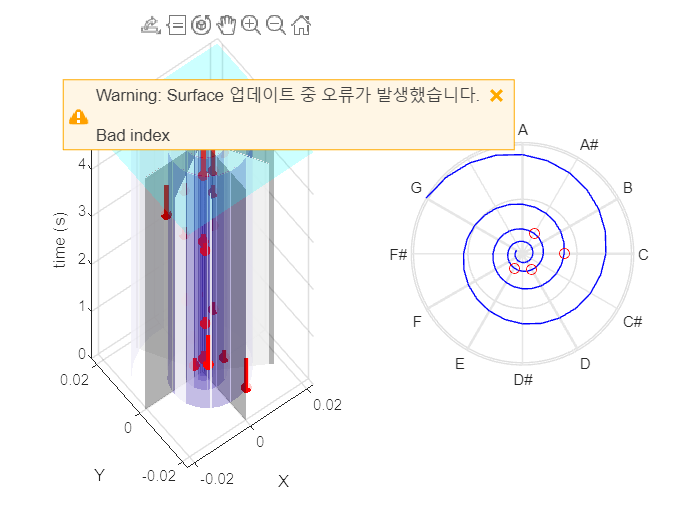

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

i = 11

i = 12

i = 13

i = 14

i = 15

i = 16

i = 17

i = 18

i = 19

i = 20

i = 21

i = 22

i = 23

i = 24


for h = 0:1/s_P:H % have to change h_p to H
    ax_3D_spir.ZData = [z_s; z_s+h];
    ax_3D_bk.ZData = [z_b; z_b+h];
    ax_3D_wk.ZData = [z_w; z_w+h];
    ax_3D_cyl.ZData = [z_c; z_c+h];

    % Z_Plane
    Z_plane.ZData = zeros(size(X))+h;

    % Find Note
    % need to modify / add final off condition ? 
    if i <= on_note_num(1)
        while (i<= on_note_num(1) && note_on(i,3)<=h)
            "<h";
            note_list = [note_list; note_on(i,:)];
            note_off_list = [note_off_list; note_off(i,:)];
            if i <= on_note_num(1)
                % pring progress
                i = i+1
            end
        end
    
        note_size = size(note_off_list);
    
        % Delete Note
        j = 1;
        while j <= note_size(1)
            if note_off_list(j,3)<=h
                ">h";
                note_list(j,:) = [];
                note_off_list(j,:) = [];
    
                j = j-1; note_size(1) = note_size(1)-1; % size update
            end
            j = j+1;
        end
    
        %{
        % -- note_off is empty
        if isempty(note_off) && i~=length(note_on)
            note = [note_on(i,:).' ; note_on(i+1,:).'];
        elseif isempty(note_off)
            note = [note_on(i,:).' ; H];
        
        % -- note_off is not empty 
        else
            note = [note_on(i,:).' ; note_off(i,3)]; % add end time ( ** modify - Working on it above )
        end
        %}
    
        %n = note(note_list); % v = note(2); st = note(3); et = note(4); 
        %n
        "draw";
        if isempty(note_list)
            Spiral_plane.XData = [];
            Spiral_plane.YData = [];
        
            Spiral_plane_line.XData = [];
            Spiral_plane_line.YData = [];
            
        else
            idx = note_list(:,1) - note_i; % MIDI note number = Matlab index

            A_s = A([idx]);
            theta_s = theta([idx]);
    
            Spiral_plane.XData = theta_s;
            Spiral_plane.YData = A_s;
        
            %Spiral_plane_line.XData = [0 theta_s];
            %Spiral_plane_line.YData = [0 A_s];
        end
    
        drawnow
    end

    drawnow
end                                                                                                       

## Synthesize MIDI Messages

This example plays parsed MIDI messages using a simple monophonic synthesizer. To see a demonstration of this synthesizer, see [Design and Play a MIDI Synthesizer](docid:audio_ug#mw_9cb34f1f-767f-42a8-b6c7-c33d9546923a). 

% Initialize System objects for playing MIDI messages
%osc = audioOscillator('square', 'Amplitude', 0,'DutyCycle',0.75);
%deviceWriter = audioDeviceWriter;

% - - Play Audio
%simplesynth(msgArray,osc,deviceWriter);

You can also send parsed MIDI messages to a MIDI device using [`midisend`](docid:audio_ref#mw_ee7bc3c1-86e5-4047-92ee-d8c60dfac44d). For more information about interacting with MIDI devices using MATLAB, see [MIDI Device Interface](docid:audio_ug#mw_66a38da2-303f-4ffe-9948-e67eb0d3fdd6).

## Helper Functions

### Read Delta-Times

function [valueOut,byteLength] = findVariableLength(lengthIndex,readOut)

byteStream = zeros(4,1);

for i = 1:4
    valCheck = readOut(lengthIndex+i);
    byteStream(i) = bitand(valCheck,127);   % Mask MSB for value
    if ~bitand(valCheck,uint32(128))        % If MSB is 0, no need to append further
        break
    end
end

valueOut = polyval(byteStream(1:i),128);    % Base is 128 because 7 bits are used for value
byteLength = i;

end

### Interpret MIDI Messages

function [statusOut,lenOut,message] = interpretMessage(statusIn,eventIn,readOut)

% Check if running status
introValue = readOut(eventIn+1);
if isStatusByte(introValue)
    statusOut = introValue;         % New status
    running = false;
else
    statusOut = statusIn;           % Running status—Keep old status
    running = true;
end

switch statusOut
    case 255     % Meta-event (FF)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+2, ...
            readOut);   % Meta-events have an extra byte for type of meta-event
        lenOut = 2+lengthLen+eventLength;
        message = -1;
    case 240     % Sysex message (F0)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
        
    case 247     % Sysex message (F7)—IGNORE
        [eventLength, lengthLen] = findVariableLength(eventIn+1, ...
            readOut);
        lenOut = 1+lengthLen+eventLength;
        message = -1;
    otherwise    % MIDI message—READ
        eventLength = msgnbytes(statusOut);
        if running  
            % Running msgs don't retransmit status—Drop a bit
            lenOut = eventLength-1;
            message = uint8([statusOut;readOut(eventIn+(1:lenOut))]);
            
        else
            lenOut = eventLength;
            message = uint8(readOut(eventIn+(1:lenOut)));
        end
end

end

% ----

function n = msgnbytes(statusByte)

if statusByte <= 191        % hex2dec('BF')
    n = 3;
elseif statusByte <= 223    % hex2dec('DF')
    n = 2;
elseif statusByte <= 239    % hex2dec('EF')
    n = 3;
elseif statusByte == 240    % hex2dec('F0')
    n = 1;
elseif statusByte == 241    % hex2dec('F1')
    n = 2;
elseif statusByte == 242    % hex2dec('F2')
    n = 3;
elseif statusByte <= 243    % hex2dec('F3')
    n = 2;
else
    n = 1;
end

end

% ----

function yes = isStatusByte(b)
yes = b > 127;
end

### Create MIDI Messages

function [tsOut,msgOut] = createMessage(messageIn,tsIn,deltaTimeIn,ticksPerQNoteIn,bpmIn)

if messageIn < 0     % Ignore Sysex message/meta-event data
    tsOut = tsIn;
    msgOut = midimsg(0);
    return
end

% Create RawBytes field
messageLength = length(messageIn);
zeroAppend = zeros(8-messageLength,1);
bytesIn = transpose([messageIn;zeroAppend]);

% deltaTimeIn and ticksPerQNoteIn are both uints
% Recast both values as doubles
d = double(deltaTimeIn);
t = double(ticksPerQNoteIn);

% Create Timestamp field and tsOut
msPerQNote = 6e7/bpmIn;
timeAdd = d*(msPerQNote/t)/1e6;
tsOut = tsIn+timeAdd;

% Create midimsg object
midiStruct = struct('RawBytes',bytesIn,'Timestamp',tsOut);
msgOut = midimsg.fromStruct(midiStruct);

end

## Play MIDI Messages Using a Synthesizer

function simplesynth(msgArray,osc,deviceWriter)

i = 1;
tic
endTime = msgArray(length(msgArray)).Timestamp;

while toc < endTime
    if toc >= msgArray(i).Timestamp     % At new note, update deviceWriter
        msg = msgArray(i);      
        i = i+1;
        if isNoteOn(msg)
            osc.Frequency = note2freq(msg.Note);
            osc.Amplitude = msg.Velocity/127;
        elseif isNoteOff(msg)
            if msg.Note == msg.Note
                osc.Amplitude = 0;
            end
        end
    end
    deviceWriter(osc());    % Keep calling deviceWriter as it is updated
end

end

% ----

function yes = isNoteOn(msg)
yes = strcmp(msg.Type,'NoteOn') ...
    && msg.Velocity > 0;
end

% ----

function yes = isNoteOff(msg)
yes = strcmp(msg.Type,'NoteOff') ...
    || (strcmp(msg.Type,'NoteOn') && msg.Velocity == 0);
end

% ----

function freq = note2freq(note)
freqA = 440;
noteA = 69;
freq = freqA * 2.^((note-noteA)/12);
end

*Copyright 2018 The MathWorks, Inc.*